# Изучение красного смещения звезд

close all
clear variables

## Импорт данных

spectra = importdata("spectra.csv")

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


lambdaStart = importdata("lambda_start.csv")

lambdaStart = 630.0200

lambdaDelta = importdata("lambda_delta.csv")

lambdaDelta = 0.1400

starNames = importdata('star_names.csv')

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


## Константы

lambdaPredicted = 656.28 %нм

lambdaPredicted = 656.2800

speedOfLight = 299792.458 %км/с

speedOfLight = 2.9979e+05

## Определение диапазона длин волн

nObs = size(spectra, 1)

nObs = 357

nStars = size(starNames, 1)

nStars = 7

lambdaEnd = lambdaStart+(nObs -1)*lambdaDelta

lambdaEnd = 679.8600

lambda =(lambdaStart : lambdaDelta : lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800


## Расчёт скорости удаления звезды от Земли

s = spectra(:,6)

s = 	1.0e+-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


[sHa, idx] = min(s)

sHa = 9.8010e-14

idx = 191

lambdaHa = lambda(idx)

lambdaHa = 656.6200


z = (lambdaHa / lambdaPredicted)-1

z = 5.1807e-04

speed = z * speedOfLight

speed = 155.3139

## Построение графика

fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [441 379 560 420]
       Units: 'pixels'

  Show all properties


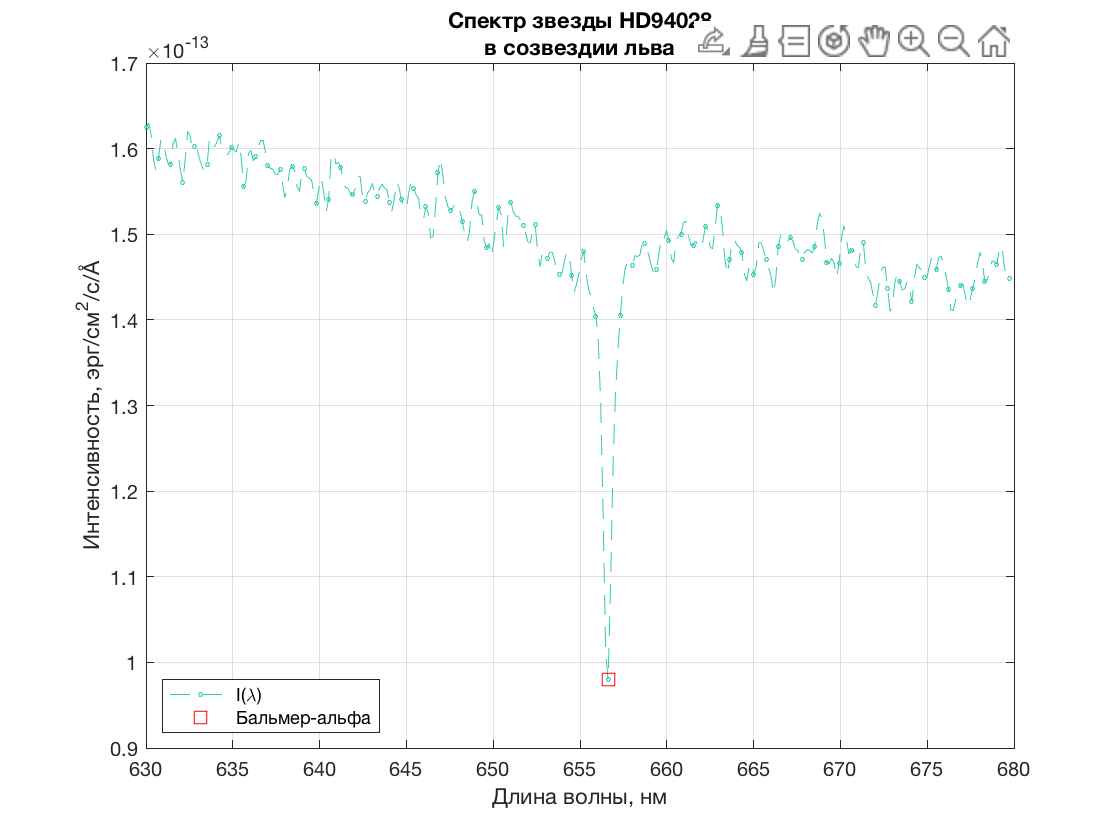

plot(lambda, s, "b--o", 'MarkerIndices',1:5:length(s), 'MarkerSize',2,"Color",[0.2 0.8 0.7])
set(gcf, 'visible', 'on')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/',char(197)])
title({'Спектр звезды HD94028', 'в созвездии льва'})
legend('I(\lambda)')
text(lambdaEnd - 20, max(s)*0,8, ['Cкорость =', num2str(speed), 'км/с'])
grid on
hold on
plot(lambdaHa, sHa, 'rs', 'MarkerSize',8)
legend('I(\lambda)','Бальмер-альфа', 'Location', 'southwest')
text(lambdaEnd - 20, max(s)*0,8, ['Cкорость =', num2str(speed), 'км/с'])
hold off

## Сохранение графика

 saveas(fg1,'spectraHD94028.png')  